## Question 3

warning off; close all; clear; clc

load 402123100-q3

u = id.u;
y = id.y;

### >>> 3.0 - Initial Assignments

N = length(y);
na = n;
nb = n;
p = na + nb;

### >>> 3.1 - ARX Modeling

U = arx_U_builder(na,nb,u,y);

theta_hat = inv(U'*U)*U'*y;
y_hat = U*theta_hat;

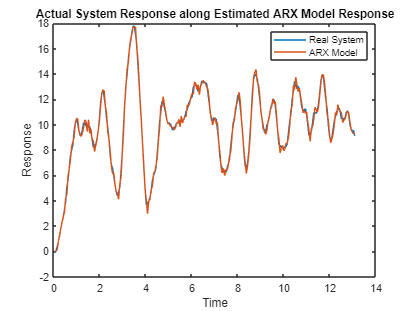

t = (id.Tstart:id.Ts:N*id.Tstart);

figure(1)
plot(t,y,t,y_hat)
title("Actual System Response along Estimated ARX Model Response")
xlabel("Time")
ylabel("Response")
legend('Real System','ARX Model')

>>> Evaluate the Estimated Model

       R2 parameter:

r2_arx = rSQR(y, y_hat)

r2_arx = 0.9910

### >>> 3.2 - IIV Modeling

first_estimation = y_hat;
% first_estimation = randn(250,1);

Z = zeros(N,p);
U = zeros(N,p);

for index_N=1:N
    for index_y=1:na
        if index_N-index_y>0
            Z(index_N,index_y) = -first_estimation(index_N-index_y);
            U(index_N,index_y) = -y(index_N-index_y);
        end
    end
    for index_x=na+1:p
        if index_N-index_x+na>0
            Z(index_N,index_x) = u(index_N-index_x+na);
            U(index_N,index_x) = u(index_N-index_x+na);
        end
    end
end

theta_hat_IV = inv(transpose(Z)*U)*transpose(Z)*y;

y_IV = U*theta_hat_IV;

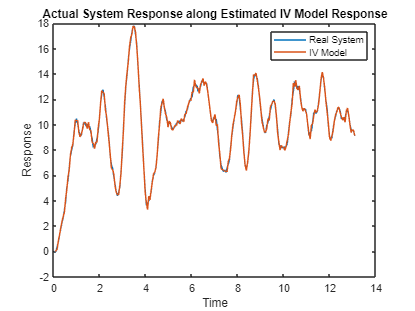

figure(2)
plot(t,y,t,y_IV)
title("Actual System Response along Estimated IV Model Response")
xlabel("Time")
ylabel("Response")
legend('Real System','IV Model')

>>> Evaluate the Estimated Model

       R2 parameter:

r2_iv = rSQR(y, y_IV)

r2_iv = 0.9959

### >>> 3.3 - ARX vs. IIV

>>> It is expected for the IIV method to leave a better performance than the ARX model and it is doing so. See the following reported R2 values for a better grasp of the results.

disp("================Model Evaaluation Report===================")

================Model Evaaluation Report===================



fprintf('------> R2 ARX  : %.7f \n', r2_arx);

------> R2 ARX  : 0.9909943 


fprintf('------> R2 IIV  : %.7f \n', r2_iv);

------> R2 IIV  : 0.9958984 



disp("===========================================================")